%defining input variables
R = 6;
C = 1*10.^-6;
L1 = 4.7*10.^-6;
L2 = 4.7*10.^-6;
L = (L1*L2)/(L1+L2);

%defining indicies
global tout
tout = 0;
global tin
tin = 0;
global microsecond
microsecond = 1;
global C1
C1 = 0;
global C2 
C2 = 0;

%defining characteristic polynomial coefficents as a function of RLC
ap = C*L

ap = 2.3500e-12

bp = L/R

bp = 3.9167e-07

cp = -1

cp = -1


%defining exponent values as a function of a characteristic polynomial
%coefficents
global s1
global s2
s1 = (-bp + sqrt(bp.^2-4.*ap.*cp))/(2.*ap)

s1 = 5.7430e+05

s2 = (-bp - sqrt(bp.^2-4.*ap.*cp))/(2.*ap)

s2 = -7.4096e+05

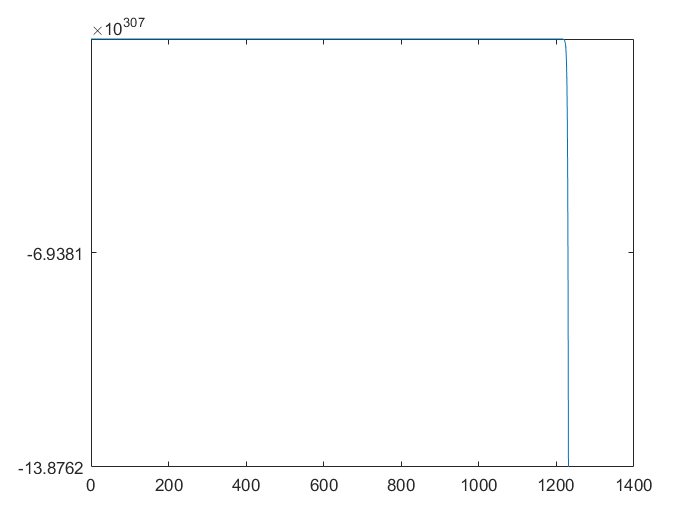



%read randomized data from .txt file
datafile = fopen("415 Data.txt", 'r');
global Vin
Vin=fscanf(datafile,'%f');
fclose(datafile);

%initalizing the output function
global Vout
Vout = zeros(1,3000000);
calcC1();
calcC2();

for tin = 1:5
    onesecond();
end

plotVout();

function calcC1() %calculate coefficent C1

    global C1;
    global s2;
    global s1;
    global Vin;
    global Vout;
    global microsecond;
    global tin;
    
    if (microsecond == 1)
        dVout = 0;
        Vinital = 0;
    elseif (microsecond == 2)
        dVout = Vout(1);
        Vinital = Vout(1);
    else
        dVout = Vout(microsecond - 2) - Vout(microsecond - 1);
        Vinital = Vout(microsecond - 1);
    end
if (tin == 0)
    C1 = (dVout - s2.*(Vinital-Vin(1)))./(s1-s2);
else
    C1 = (dVout - s2.*(Vinital-Vin(tin)))./(s1-s2);
end

end

%calculate coefficent C2
function calcC2()

    global C1;
    global C2;
    global Vin;
    global Vout;
    global microsecond;
    global tin;

 if (microsecond == 1)
        Vinital = 0;
    elseif (microsecond == 2)
        Vinital = Vout(1);
    else
        Vinital = Vout(microsecond - 1);
 end
 if (tin == 0)
    C2 = Vinital - Vin(1) - C1;
else
    C2 = Vinital - Vin(tin) - C1;
end
    

end

%evaluate Vout for one second (one interation of Vin)
function onesecond()
    global Vout
    global Vin
    global microsecond
    global tout
    global tin
    global s1
    global s2
    global C1
    global C2
   
    calcC1(); %calculate coefficents for the step response
    calcC2();
    
    for tout=1:1000000 %for every microsecond in the second
    Vout(microsecond) = C1*exp(s1*tout*0.000001) + C2*exp(s2*tout*0.000001) + Vin(tin); %set Vout for that microsecond
    microsecond = microsecond + 1; %increment index of Vout
    end
end

function plotVout()
global Vout
   t = linspace(0, length(Vout), length(Vout));
   plot(t, Vout);
end